# Ajuste por mínimos cuadrados

Se quiere realizar un ajuste de la forma $y\;=a_1 t+a_0$ de los siguientes datos:

t = [0 3 4 7 9];
x = [0 30 60 90 120];

P = polyfit(t, x, 1);

syms t1
disp(vpa(poly2sym(P, t1), 4));

$$13.41\,t_{1}-1.707$$

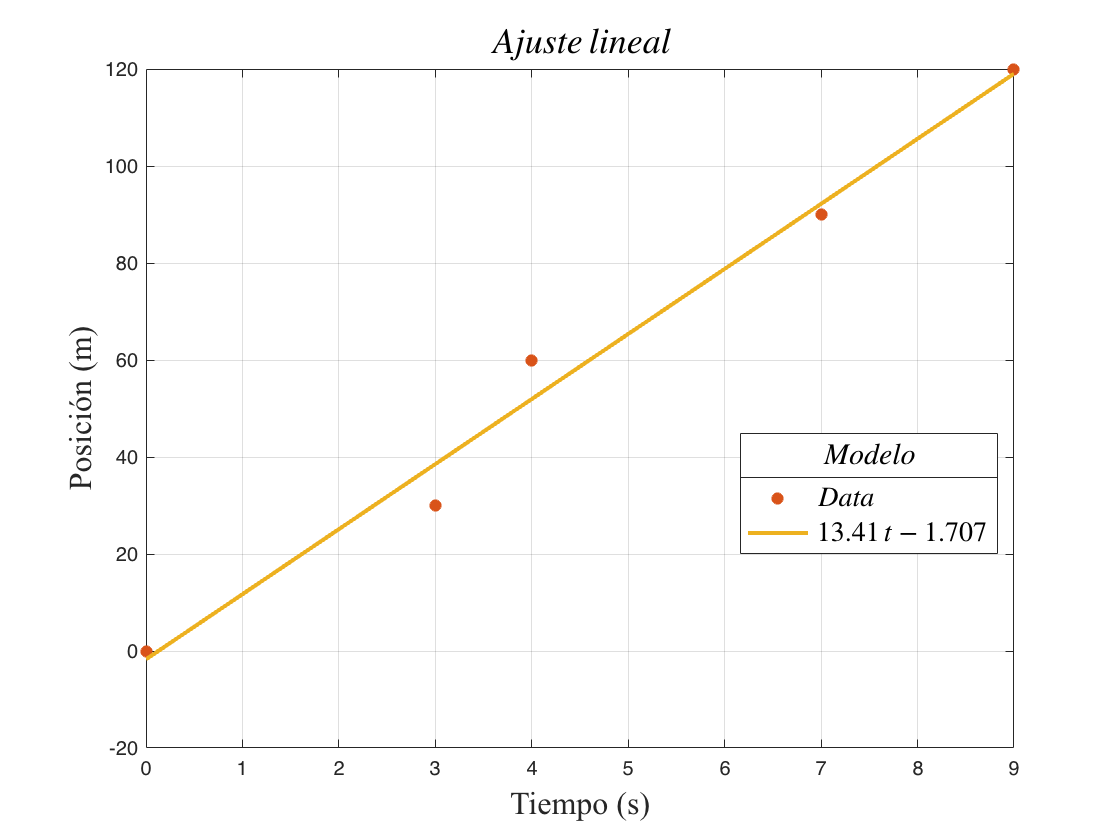

tt = linspace(min(t), max(t));
xx = polyval(P, tt);

plot(t, x, '*', Color='#D95319', LineWidth=2);
hold on; grid on;
plot(tt, xx, Color='#EDB120', LineWidth=2);
hold off;
title('$Ajuste\,lineal$', 'Interpreter','latex', 'FontSize', 18)
xlabel('Tiempo (s)', 'FontName','Times New Roman', 'FontSize', 16)
ylabel('Posición (m)', 'FontName','Times New Roman', 'FontSize', 16)

lgnd = legend('$Data$', '$13.41\,t-1.707$', 'Interpreter','latex', 'Location','best', 'FontSize', 14);
title(lgnd, '$Modelo$', 'Interpreter','latex', 'FontSize', 15)
hold off;

Se quiere realizar un ajuste exponencial de la forma $y\;=\;A*e^{B*x}$ de los siguientes datos:

x = [6 10 12 14 16 20]';
y = [23.34 19.67 18.52 17.6 16.81 15.9]';

help LinealizacionExponencial

  Función que calcula los coeficientes (A) y (B)
  de un ajuste exponencial tal que
  y = A*e^(B*x)
  
  Linealizando la función:
  ln(y) = ln(A) + B*x
       ↓
  ln(y) = C, ln(A) = D
  
  C = B*x + D



[A, B] = LinealizacionExponencial(x, y);

g = @(x) (A.*exp(B.*x));
disp(vpa(sym(g), 5))

$$26.336\,{\mathrm{e}}^{-0.027197\,x}$$

plot(x, y, '*', Color='#D95319', LineWidth=2);
hold on;
grid on;

fplot(g, [min(x) max(x)], Color='#7E2F8E', LineWidth=2)
title("$Ajuste\,exponencial$", 'Interpreter','latex', 'FontSize',20)

lgnd = legend('$Data$', '$26.336\,{\mathrm{e}}^{-0.027\,x}$', 'FontSize',16, 'Interpreter','latex', Location='best');
title(lgnd, '$Modelo$', Interpreter='latex')

xlabel('Calibre', 'FontSize',16, 'FontName','Times New Roman')
ylabel('Diametro del Cañón (mm)', 'FontSize',16, 'FontName','Times New Roman')
hold off;

# Interpolación polinomial

Se necesitan $\left(N+1\right)$ puntos para formar un polinomio $P\left(x\right)$ de grado máximo $N$ tal que $P\left(x_i \right)=y_i \;\forall \;i=\left\lbrace 0,1,\ldotp \ldotp \ldotp ,N\right\rbrace$.

x = [2 3 5 6 8]';
y = [10 20 15 30 25]';
n = length(x);

P = polyfit(x, y, n-1);
disp(vpa(poly2sym(P), 5))

$$-0.80556\,x^{4}+15.389\,x^{3}-102.47\,x^{2}+282.33\,x-255.0$$

xx = linspace(min(x), max(x));
yy = polyval(P, xx);

layout = tiledlayout('flow','TileSpacing','compact');

nexttile

plot(xx, yy, 'Color', '#0072BD', LineWidth = 2)
grid on; hold on;
plot(x, y, '*', 'Color', '#A2142F', LineWidth = 2);

title("Polinomio de interpolación de grado N", "FontSize", 18, "FontName", "Times New Roman")
xlabel('$x$', 'Interpreter','latex', "FontSize", 18);
ylabel('$g(x)$', 'Interpreter','latex', "FontSize", 18)

lgnd = legend('$Data$', '$g(x)=-0.80556\,x^4 +15.389\,x^3 -102.47\,x^2 +282.33\,x-255.0$', 'Interpreter', 'latex', "FontSize", 15, Location='best');
title(lgnd, 'Modelo', 'FontName', 'Times New Roman', "FontSize", 16)

lgnd.Layout.Tile = 2;
hold off;

# Interpolación a trozos

Se crean $N$ polinomios de grado máximo 3 que definen un único spline cúbico natural para interpolar $\left(N+1\right)$ puntos de forma suave. A diferencia de los métodos de interpolación clásicos, este método requiere que los $x_i$ se brinden en orden ascendente. 


$$S_i \left(t\right)={a\left(t-t_i \right)}^3 +{b\left(t-t_i \right)}^2 +c\left(t-t_i \right)+d\;\;\forall \;\;\;\;i=0,1,\ldotp \ldotp \ldotp ,N-1$$


x = [2 3 5 6 8];
y = [10 20 15 30 25];

help SplineCubicoNatural

  Función que calcula el spline cúbico natural (S) de una serie de puntos
  (x[i]), (y[i]) ∀ i = {0, 1, ..., N} mediante N polinomios de grado máximo 3
  que describen el spline a trozos.
  
 
  • Condición de interpolación: 
  S(x[i]) = y[i] ∀ i = {0, 1, ..., N}
 
  • Condición de continuidad:
  S[i-1](x[i]) = S[i](x[i]) ∀ i = {1, ..., N-1}
  
  • Condición de suavidad:      
  S'[i-1](x[i]) = S'[i](x[i]) ∀ i = {1, ..., N-1}
  
  • Condición de Spline Cubico Natural: 
  S"(x[0]) = 0 & S"(x[N]) = 0



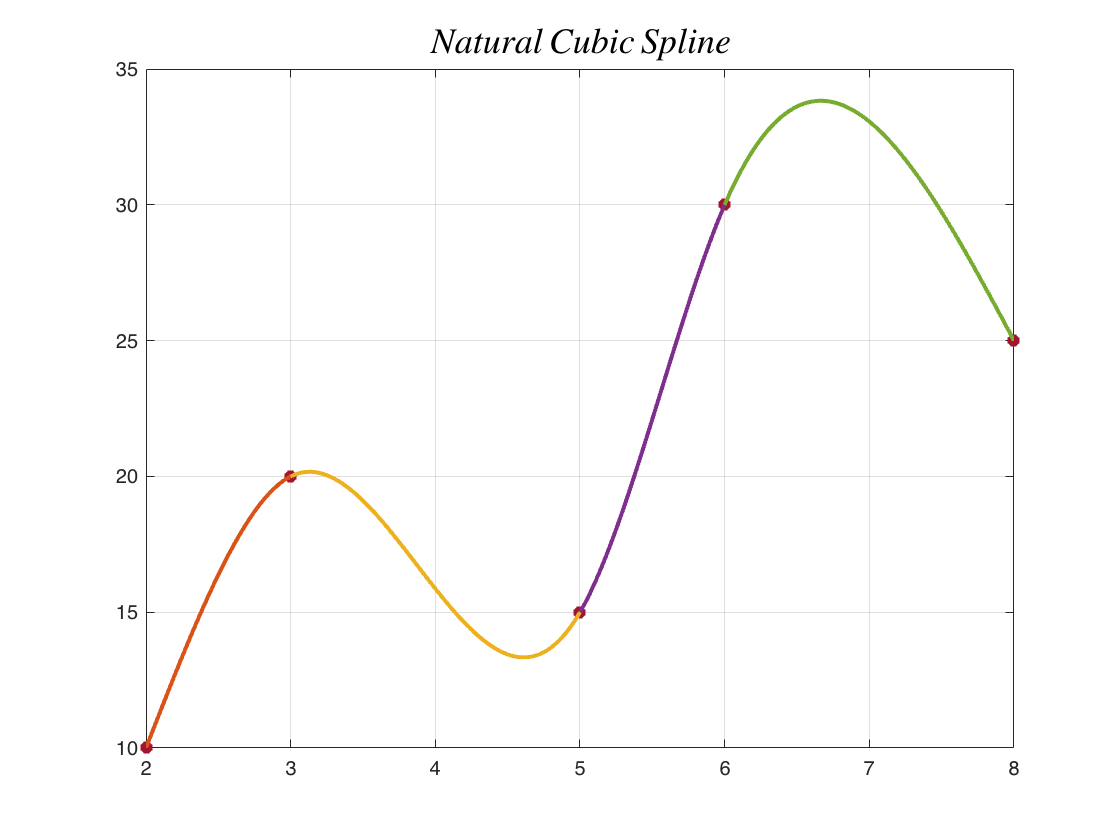

    i    x    y     h[i]    f[x(i),x(i+1)]    S"(x[i])
    _    _    __    ____    ______________    ________

    0    2    10      1            10               0 
    1    3    20      2          -2.5         -22.016 
    2    5    15      1            15          28.548 
    3    6    30      2          -2.5         -22.258 
    4    8    25    NaN           NaN               0 

    i    (x-x[i])       a          b         c       d     [x[i], x[i+1]] 
    _    ________    _______    _______    ______    __    _______________

    0    "(x-2)"    

SplineCubicoNatural(x, y);